# Laboratorio 3 - Modelo diferencial de primer orden

#### Grupo 8

Ardila, Juan Andrés

López, Nicolás

Rojas, Juan Camilo

Nuestro robot: Fanuc R-2000iC/125L

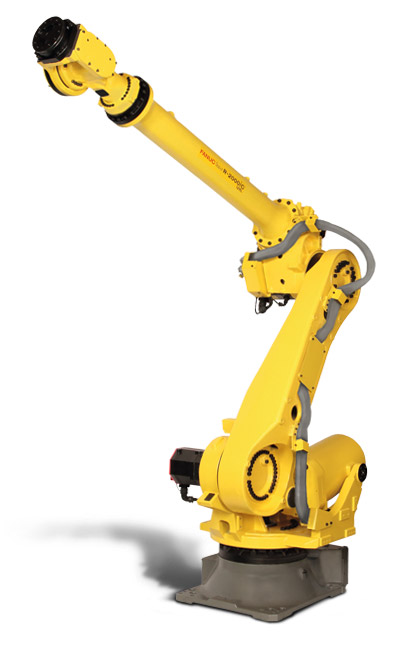

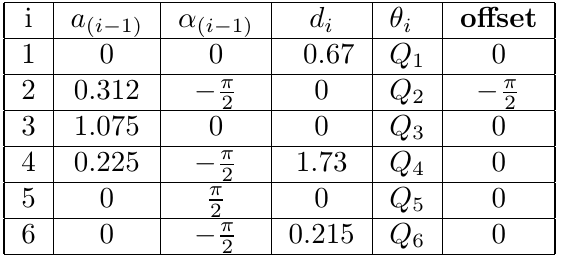

- Con los valores numéricos de longitudes y desplazamientos de los eslabones del robot asignado obtenga el Jacobiano (como una matriz de valores numéricos, NO simbólicos) en función de los ángulos de articulación. 

La de arriba es la tabla de DH mod, para esta lab utilizaremos la DH estándar:

clear;
L(1) = Link('revolute','alpha',-pi/2,'a', 0.312,'d',0.67, 'offset',0,  ...
    'standard', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha',0,    'a', 1.075,'d',0,    'offset',-pi/2,...
    'standard', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha',-pi/2,'a', 0.225,'d',0,    'offset',0, ...
    'standard', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha',pi/2, 'a', 0,    'd',1.73, 'offset',0, ...
    'standard', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha',-pi/2,'a', 0,    'd',0,    'offset',0, ...
    'standard', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha',0,    'a', 0,    'd',0.215,'offset',0, ...
    'standard', 'qlim',[-pi pi]);

Robot = SerialLink(L,'name','R_{Fanuc}')

 
Robot = 
 
R_{Fanuc} (6 axis, RRRRRR, stdDH, fastRNE)                       
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|       0.67|      0.312|     -1.571|          0|
|  2|         q2|          0|      1.075|          0|     -1.571|
|  3|         q3|          0|      0.225|     -1.571|          0|
|  4|         q4|       1.73|          0|      1.571|          0|
|  5|         q5|          0|          0|     -1.571|          0|
|  6|         q6|      0.215|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0            


%Posición de las articulaciones del robot
q = [0 pi/2 0 -pi/2 0 0];

A_0_1 = L(1).A(q(1))

A_0_1 =     1.0000         0         0    0.3120
         0    0.0000    1.0000         0
         0   -1.0000    0.0000    0.6700
         0         0         0    1.0000


A_1_2 = L(2).A(q(2))

A_1_2 =     1.0000         0         0    1.0750
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


A_2_3 = L(3).A(q(3))

A_2_3 =     1.0000         0         0    0.2250
         0    0.0000    1.0000         0
         0   -1.0000    0.0000         0
         0         0         0    1.0000


A_3_4 = L(4).A(q(4))

A_3_4 =     0.0000    0.0000   -1.0000         0
   -1.0000    0.0000   -0.0000         0
         0    1.0000    0.0000    1.7300
         0         0         0    1.0000


A_4_5 = L(5).A(q(5))

A_4_5 =     1.0000         0         0         0
         0    0.0000    1.0000         0
         0   -1.0000    0.0000         0
         0         0         0    1.0000


A_5_6 = L(6).A(q(6))

A_5_6 =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000    0.2150
         0         0         0    1.0000



%Valores absolutos de 1 a 6
T_0_1 = A_0_1 * eye(4)

T_0_1 =     1.0000         0         0    0.3120
         0    0.0000    1.0000         0
         0   -1.0000    0.0000    0.6700
         0         0         0    1.0000


T_0_2 = A_0_1 * A_1_2 * eye(4)

T_0_2 =     1.0000         0         0    1.3870
         0    0.0000    1.0000         0
         0   -1.0000    0.0000    0.6700
         0         0         0    1.0000


T_0_3 = A_0_1 * A_1_2 * A_2_3 * eye(4)

T_0_3 =     1.0000         0         0    1.6120
         0   -1.0000    0.0000         0
         0   -0.0000   -1.0000    0.6700
         0         0         0    1.0000


T_0_4 = A_0_1 * A_1_2 * A_2_3 * A_3_4 * eye(4)

T_0_4 =     0.0000    0.0000   -1.0000    1.6120
    1.0000    0.0000    0.0000    0.0000
    0.0000   -1.0000   -0.0000   -1.0600
         0         0         0    1.0000


T_0_5 = A_0_1 * A_1_2 * A_2_3 * A_3_4 * A_4_5 * eye(4)

T_0_5 =     0.0000    1.0000         0    1.6120
    1.0000   -0.0000    0.0000    0.0000
    0.0000   -0.0000   -1.0000   -1.0600
         0         0         0    1.0000


T_0_6 = A_0_1 * A_1_2 * A_2_3 * A_3_4 * A_4_5 * A_5_6 * eye(4)

T_0_6 =     0.0000    1.0000         0    1.6120
    1.0000   -0.0000    0.0000    0.0000
    0.0000   -0.0000   -1.0000   -1.2750
         0         0         0    1.0000



%Las Z
Z_0 = [0; 0; 1]

Z_0 =      0
     0
     1


Z_1 = [T_0_1(1,3); T_0_1(2,3); T_0_1(3,3)]

Z_1 =          0
    1.0000
    0.0000


Z_2 = [T_0_2(1,3); T_0_2(2,3); T_0_2(3,3)]

Z_2 =          0
    1.0000
    0.0000


Z_3 = [T_0_3(1,3); T_0_3(2,3); T_0_3(3,3)]

Z_3 =          0
    0.0000
   -1.0000


Z_4 = [T_0_4(1,3); T_0_4(2,3); T_0_4(3,3)]

Z_4 =    -1.0000
    0.0000
   -0.0000


Z_5 = [T_0_5(1,3); T_0_5(2,3); T_0_5(3,3)]

Z_5 =          0
    0.0000
   -1.0000



%Posiciones absolutas de los sistemas de referencia
T_0 = [0; 0; 0]

T_0 =      0
     0
     0


T_1 = [T_0_1(1,4); T_0_1(2,4); T_0_1(3,4)]

T_1 =     0.3120
         0
    0.6700


T_2 = [T_0_2(1,4); T_0_2(2,4); T_0_2(3,4)]

T_2 =     1.3870
         0
    0.6700


T_3 = [T_0_3(1,4); T_0_3(2,4); T_0_3(3,4)]

T_3 =     1.6120
         0
    0.6700


T_4 = [T_0_4(1,4); T_0_4(2,4); T_0_4(3,4)]

T_4 =     1.6120
    0.0000
   -1.0600


T_5 = [T_0_5(1,4); T_0_5(2,4); T_0_5(3,4)]

T_5 =     1.6120
    0.0000
   -1.0600


T_6 = [T_0_6(1,4); T_0_6(2,4); T_0_6(3,4)]

T_6 =     1.6120
    0.0000
   -1.2750



%Jacobiano
J = [cross(Z_0,(T_6-T_0)) cross(Z_1,(T_6-T_1)) cross(Z_2,(T_6-T_2))...
    cross(Z_3,(T_6-T_3)) cross(Z_4,(T_6-T_4)) cross(Z_5,(T_6-T_5));
    Z_0 Z_1 Z_2 Z_3 Z_4 Z_5]

J =    -0.0000   -1.9450   -1.9450   -0.0000   -0.0000   -0.0000
    1.6120    0.0000    0.0000         0   -0.2150         0
         0   -1.3000   -0.2250         0   -0.0000         0
         0         0         0         0   -1.0000         0
         0    1.0000    1.0000    0.0000    0.0000    0.0000
    1.0000    0.0000    0.0000   -1.0000   -0.0000   -1.0000


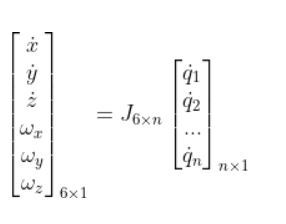

Ya se obtuvo el Jacobiano, ahora toca obtener el inverso.

Ahora para el punto 2. Para una postura de su elección dentro del espacio diestro del robot obtenga las velocidades de articulación para:

Como nuestro Jacobiano es cuadrado simplemente se encuentra el inverso del jacobiano de manera tradicional.

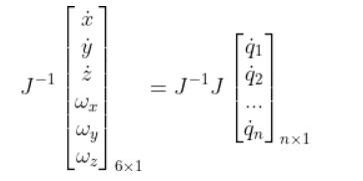

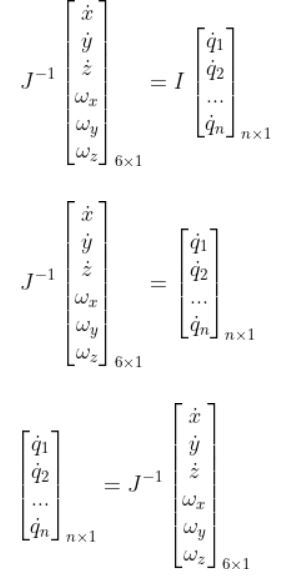

Jinv = pinv(J)

Jinv =    -0.0000    0.6203    0.0000   -0.1334   -0.0000    0.0000
    0.0851    0.0000   -0.9302   -0.0000   -0.0438   -0.0000
   -0.4918   -0.0000    0.9302   -0.0000    0.2528   -0.0000
   -0.0000    0.3102    0.0000   -0.0667    0.0000   -0.5000
   -0.0000    0.0000    0.0000   -1.0000    0.0000    0.0000
    0.0000    0.3102   -0.0000   -0.0667   -0.0000   -0.5000


Para obtener la respuesta con los valores propuestos luego hacemos:

V_H = [100;200;50]

V_H =    100
   200
    50


w_H = [5;10;-5]

w_H =      5
    10
    -5


vector = [V_H;w_H]

vector =    100
   200
    50
     5
    10
    -5


q_punto = Jinv*vector

q_punto =   123.4026
  -38.4380
   -0.1359
   64.2013
   -5.0000
   64.2013


Ubique la ruta seleccionada con la orientaci´on indicada dentro del espacio diestro del robot

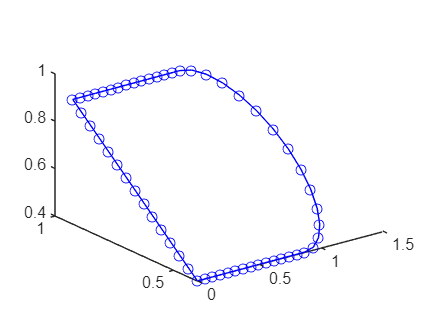

horizontal = 3.1;
L = 0.4*horizontal;

r = 0.3*L;
n = 15;

t1 = [linspace(0,L-r,n)' zeros(n,2)];
theta = linspace(-pi/2,pi/2, n);
cx = (L-r);
cy = r;
cz = 0;

t2 = [cx+r*cos(theta)' cy+r*sin(theta)' cz+0.*theta'];
t3 = [t2(end,:);linspace(L-r,0,n)' 2*r.*ones(n,1) zeros(n,1)];
t4 = [t3(end,:);zeros(n,1) linspace(2*r,0,n)' zeros(n,1)];

ruta = [t1; t2; t3; t4];

clf
R0_t = rotx(45,'deg');
p0_t = [0 0.4 0.4];
ruta_ = 0.*ruta;
for i=1:length(ruta(:,1))
    ruta_(i,:) = R0_t*ruta(i,:)'+p0_t';
end

figure (1)
plot3(ruta_(:,1),ruta_(:,2),ruta_(:,3),'-bo')

Calcule las configuraciones correspondientes a cada viapoint. Presente una gráfica de cada ángulo de articulación al recorrer la ruta.

Para esto se crea el robot con el RST

robot = rigidBodyTree;
body1 = rigidBody('body1'); 
body2 = rigidBody('body2'); 
body3 = rigidBody('body3'); 
body4 = rigidBody('body4'); 
body5 = rigidBody('body5'); 
body6 = rigidBody('body6'); 
bodyEndEffector=rigidBody('endeffector');
jnt1 = rigidBodyJoint('jnt1','revolute');
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt3 = rigidBodyJoint('jnt3','revolute');
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt5 = rigidBodyJoint('jnt5','revolute');
jnt6 = rigidBodyJoint('jnt6','revolute');
%body1
tform1 = transl(0, 0, 0.67);
setFixedTransform(jnt1,tform1); 
body1.Joint = jnt1;
addBody(robot,body1,'base')

%body2
tform2 = transl(0.312, 0, 0)*trotx(-pi/2)*trotz(-pi/2);
setFixedTransform(jnt2,tform2);
%setFixedTransform(jnt2,dhparams(2,:),'dh'); 
body2.Joint = jnt2;
addBody(robot,body2,'body1')

%body3
tform3 = transl(1.075, 0, 0);
setFixedTransform(jnt3,tform3);
body3.Joint = jnt3;
addBody(robot,body3,'body2')

%body4
tform4 = transl(0.225, 1.73, 0)*trotx(-pi/2);
setFixedTransform(jnt4,tform4);
body4.Joint = jnt4;
addBody(robot,body4,'body3')

%body5
tform5 = transl(0, 0, 0)*trotx(pi/2);
setFixedTransform(jnt5,tform5);
body5.Joint = jnt5;
addBody(robot,body5,'body4')

%body6
tform6 = transl(0, 0.215, 0)*trotx(-pi/2);
setFixedTransform(jnt6,tform6);
body6.Joint = jnt6;
addBody(robot,body6,'body5')

%endEffector
tform7 = trvec2tform([0 0 0]);
setFixedTransform(bodyEndEffector.Joint,tform7);
addBody(robot,bodyEndEffector,'body6')

Ahora la cinemática inversa

ik = inverseKinematics('RigidBodyTree', robot);
weights = [0.25 0.25 0.25 1 1 1];
initialguess = homeConfiguration(robot);
robot.BodyNames

ans = 1×7 cell array
    {'body1'}    {'body2'}    {'body3'}    {'body4'}    {'body5'}    {'body6'}    {'endeffector'}



viapoints = length(ruta(:,1));
conf_ruta = zeros(viapoints,6);
for i=1:viapoints
    tic
    if i>1
        initialguess = configSoln;
    end
    p0_t = ruta_(i,:);
    R0_t = rotx(-135,'deg');
    MTHpose = [R0_t p0_t'; 0 0 0 1];
    [configSoln,solnInfo] = ik('endeffector',MTHpose,weights,initialguess);
    conf_ruta(i,:) = [configSoln(1).JointPosition configSoln(2).JointPosition configSoln(3).JointPosition ...
        configSoln(4).JointPosition configSoln(5).JointPosition configSoln(6).JointPosition];
    rutaxd(i,:) = configSoln';
    disp(strcat(num2str(i),"/",num2str(viapoints)))
    toc
end

1/62


Elapsed time is 1.529759 seconds.


2/62


Elapsed time is 1.139363 seconds.


3/62


Elapsed time is 1.109545 seconds.


4/62


Elapsed time is 1.120482 seconds.


5/62


Elapsed time is 0.056985 seconds.


6/62


Elapsed time is 0.016965 seconds.


7/62


Elapsed time is 0.017724 seconds.


8/62


Elapsed time is 0.014877 seconds.


9/62


Elapsed time is 0.016785 seconds.


10/62


Elapsed time is 0.014277 seconds.


11/62


Elapsed time is 0.022185 seconds.


12/62


Elapsed time is 0.013421 seconds.


13/62


Elapsed time is 0.020097 seconds.


14/62


Elapsed time is 0.014232 seconds.


15/62


Elapsed time is 0.017833 seconds.


16/62


Elapsed time is 0.001729 seconds.


17/62


Elapsed time is 0.011578 seconds.


18/62


Elapsed time is 0.016050 seconds.


19/62


Elapsed time is 0.300555 seconds.


20/62


Elapsed time is 0.017400 seconds.


21/62


Elapsed time is 0.020733 seconds.


22/62


Elapsed time is 0.019142 seconds.


23/62


Elapsed time is 0.015632 seconds.


24/62


Elapsed time is 0.016557 seconds.


25/62


Elapsed time is 0.012663 seconds.


26/62


Elapsed time is 0.012767 seconds.


27/62


Elapsed time is 0.016200 seconds.


28/62


Elapsed time is 0.018023 seconds.


29/62


Elapsed time is 0.019382 seconds.


30/62


Elapsed time is 0.023467 seconds.


31/62


Elapsed time is 0.001816 seconds.


32/62


Elapsed time is 0.001614 seconds.


33/62


Elapsed time is 0.030988 seconds.


34/62


Elapsed time is 0.013732 seconds.


35/62


Elapsed time is 0.018488 seconds.


36/62


Elapsed time is 0.013199 seconds.


37/62


Elapsed time is 0.018421 seconds.


38/62


Elapsed time is 0.018394 seconds.


39/62


Elapsed time is 0.021597 seconds.


40/62


Elapsed time is 0.030154 seconds.


41/62


Elapsed time is 0.117094 seconds.


42/62


Elapsed time is 0.017266 seconds.


43/62


Elapsed time is 0.021038 seconds.


44/62


Elapsed time is 0.020200 seconds.


45/62


Elapsed time is 0.020526 seconds.


46/62


Elapsed time is 0.012671 seconds.


47/62


Elapsed time is 0.001558 seconds.


48/62


Elapsed time is 0.004746 seconds.


49/62


Elapsed time is 0.009840 seconds.


50/62


Elapsed time is 0.009383 seconds.


51/62


Elapsed time is 0.008909 seconds.


52/62


Elapsed time is 0.017625 seconds.


53/62


Elapsed time is 0.011214 seconds.


54/62


Elapsed time is 0.017445 seconds.


55/62


Elapsed time is 0.011675 seconds.


56/62


Elapsed time is 0.013867 seconds.


57/62


Elapsed time is 0.010487 seconds.


58/62


Elapsed time is 0.014392 seconds.


59/62


Elapsed time is 0.019099 seconds.


60/62


Elapsed time is 1.331818 seconds.


61/62


Elapsed time is 1.248868 seconds.


62/62


Elapsed time is 1.347070 seconds.


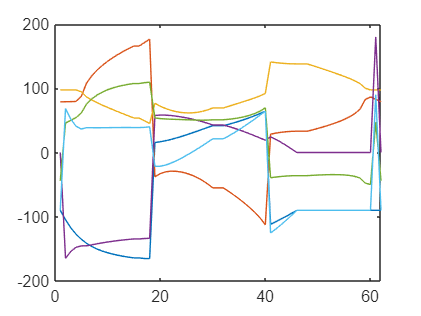


figure (2)
plot(conf_ruta(:,1)*180/pi)
hold on
plot(conf_ruta(:,2)*180/pi)
hold on
plot(conf_ruta(:,3)*180/pi)
hold on
plot(conf_ruta(:,4)*180/pi)
hold on
plot(conf_ruta(:,5)*180/pi)
hold on
plot(conf_ruta(:,6)*180/pi)
hold off

Animación del Robot (esta sección debe copiarse en el command window ya que al reproducirlo acá aparece error):

% fps=60;r=rateControl(fps);
% show(robot,rutaxd(1,:))
% ax=gca;
% hold on
% plot3(ax,ruta_(:,1),ruta_(:,2),ruta_(:,3),'-bo');
% hold on
% while true
% for i=1:viapoints
%     show(robot,rutaxd(i,:),'PreservePlot',false);
%     drawnow
%     waitfor(r);
% end
% end

Para la velocidad fija en la trayectoria (500mm/s):

Jacobianos = cell(1,viapoints);
for i=1:viapoints
    Jacobianos{i} = geometricJacobian(robot,rutaxd(i,:),'endeffector');
end

tiempos = zeros(61,1);
distancia_tot = 0;
distancias = zeros(61,3); 
velocidad = 0.5;
for j=1:viapoints-1
    norma = norm(ruta_(j+1,:)-ruta_(j,:)); 
    distancia_tot = distancia_tot + norma;
    if norma ~= 0
        distancias(j,:) = (ruta_(j+1,:)-ruta_(j,:));
        tiempos(j) = norma/velocidad;
    else
        distancias(j,:) = [0 0 0];
    end
end

Para la velocidad lineal instantánea:

v = zeros(61,3);
for k=1:viapoints-1
    if(tiempos(k) ~= 0)
        v(k,:) = (distancias(k)/tiempos(k));
    else
        v(k,:) = [0 0 0];
    end
end
v = [[0 0 0]; v];
w = zeros(62,3);
vw = [v, w];
q_punto = zeros(6,62);

for i=1:viapoints
    q_punto(:,i) = inv(Jacobianos{i})*vw(i,:)';
end

t = zeros(62,1);
for i = 2 : viapoints
    t(i) = t(i-1) + tiempos(i-1);
end 

Graficando:

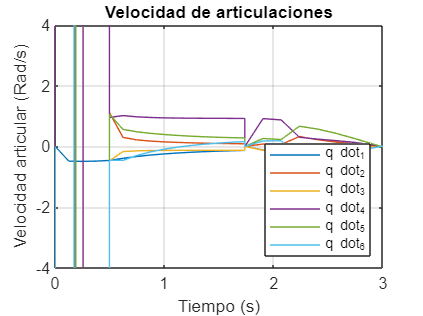

clf
for i=1:6
    plot(t,q_punto(i,:), 'DisplayName',['q dot_',num2str(i)])
    hold on
end
legend('Location',"southeast")
grid on
hold off
title('Velocidad de articulaciones')
xlim([0.00 3.00])
ylim([-4.00 4.00])
xlabel('Tiempo (s)')
ylabel('Velocidad articular (Rad/s)')